# Transforms: Asset rotation, translation, and scaling

This tutorial shows how to rotate, scale and translate an object using iset3D. We illustrate the transforms by applying them to a cube with different colored sides.

The order of operations in PBRT follows the order of operations that you define by the series of recipe.sets(). 

We recommend that you use the (translate, rotate, scale) order of operations. We find it helpful to think the effects when using this order. 

- Translate the object to the desired position. The translation is always applied in the world coordinate frame.

- Rotate the object. The rotation is applied in the object's coordinate frame.

- Scale the object. The scale is applied to the object, AND PBRTalso applies the scale to and subsquent translations. As a consequence, translate-scale is not the same as scale-translate. The scale does NOT apply to the rotation.

The sequence of transforms is stored in the branch node in the transorder slot. The nodes can include multiple transforms of each time. 

Finally, each branch node can have multiple object nodes as children. There can also be additional branch nodes as a child.

**Depends on: **

   ISET3d, Docker, ISET

**See also:**

  t_piIntro*

## Initialize

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read in the base scene

thisR = piRecipeDefault('scene name','coloredCube');

Read 1 materials.
Read 1 textures.
***Scene parsed.


## Render the original scene first

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  25.2 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


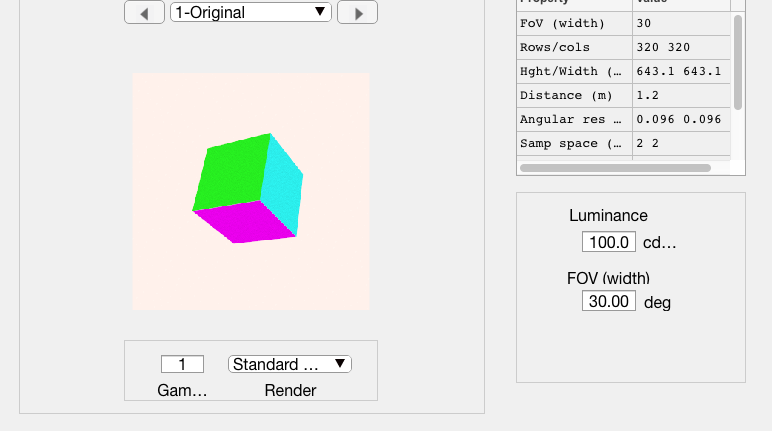

piWRS(thisR,'render type','radiance','name','Original'); 

## Rotate the cube

The different sides of the cube are individual assets with their own colors.  They have IDs that end with an _O that means they are objects (leafs of the tree).  There is a  branch node that defines the transforms for all of these objects.  That transform node is above the collection of these object nodes.

Get the branch node that defines the Cube transforms

nodeName = 'Cube_B'; 
thisNode = thisR.get('node',nodeName);

Rotate this node 45 deg counter-clockwise around the z-axis. The rotation will be inherited by all of the cube sides.

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  26.5 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


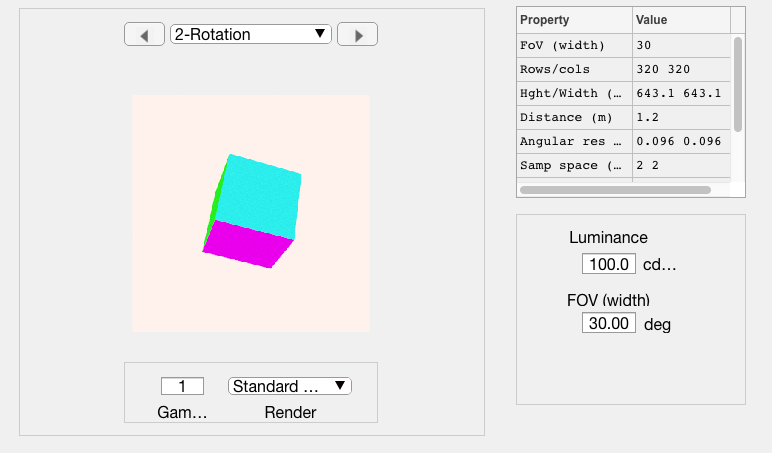

thisR.set('node', thisNode.name, 'rotate', [0, 0, 45]);
piWRS(thisR,'name','Rotation','render type','radiance');

## Scale the cube

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  21.7 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


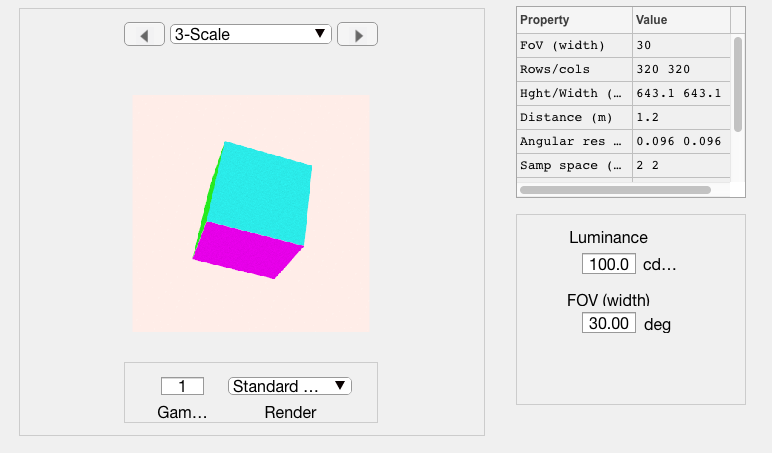

thisR.set('node', thisNode.name, 'scale', [1.2 1.2 1.2]);
piWRS(thisR,'name','Scale','render type','radiance');

## Translate the cube

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  21.5 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


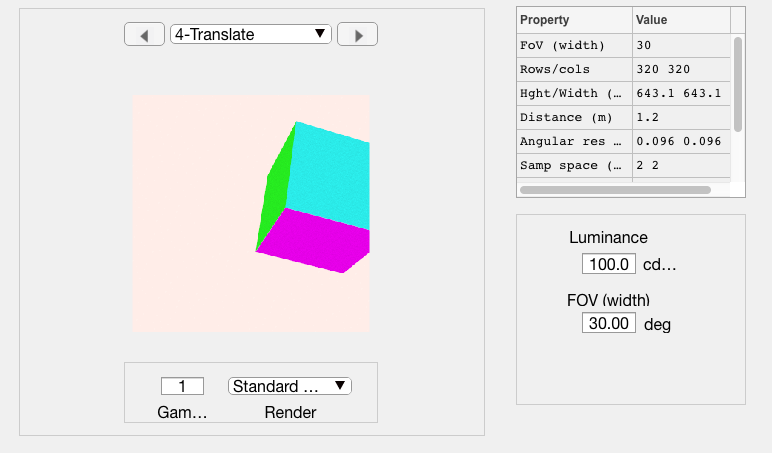

% Translation in meters
thisR.set('node', thisNode.name, 'translate', [0.3 0.3 0]);
piWRS(thisR,'name','Translate','render type','radiance');

## Here is the current world position of the object

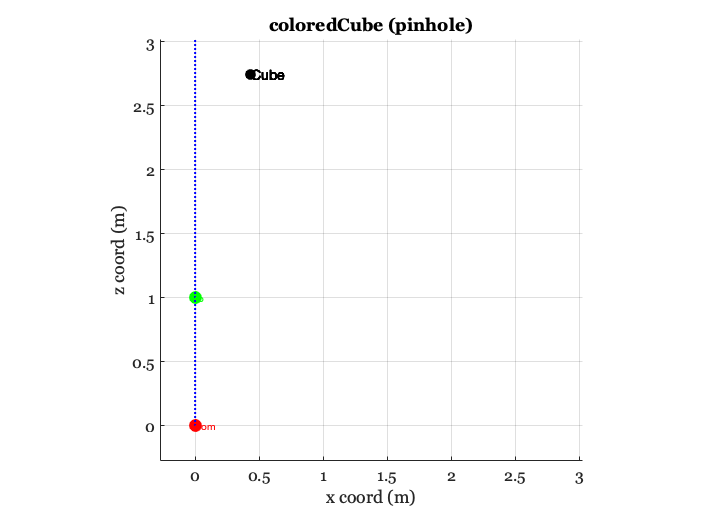

currentP = thisR.get('node',thisNode.name,'world position');
piAssetGeometry(thisR);

## Bring the object closer, specifying world position

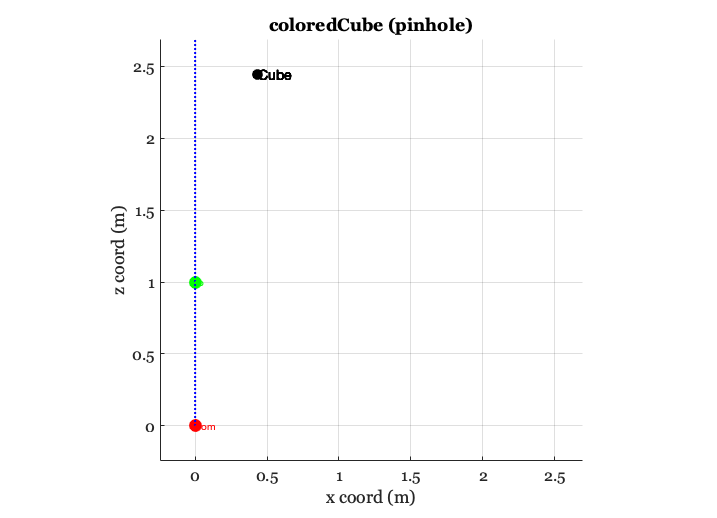

thisR.set('node',thisNode.name,'world position',currentP + [0 0 -0.3]);
piAssetGeometry(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  66.4 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


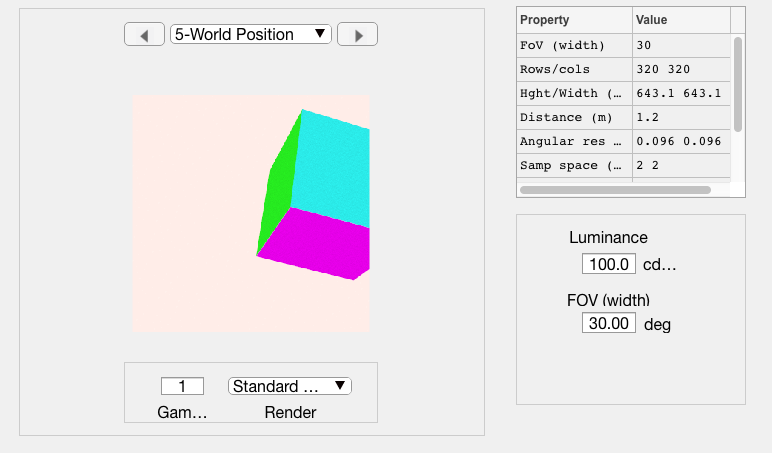

piWRS(thisR,'render type','radiance','name','World Position'); 

## The order of operations between scale and rotate does not matter: scale-rotate

thisR = piRecipeDefault('scene name','coloredCube');

Read 1 materials.
Read 1 textures.
***Scene parsed.


Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt


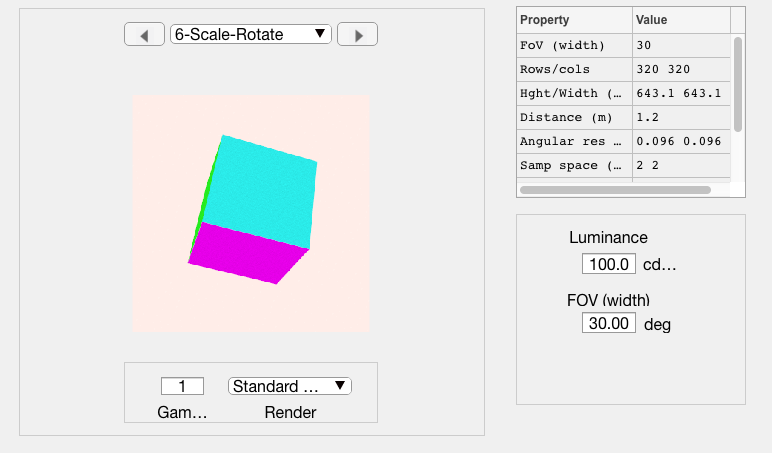

thisR.set('node', thisNode.name, 'scale', [1.3 1.3 1.3]);
thisR.set('node', thisNode.name, 'rotate', [0 0 45]);
piWRS(thisR,'name','Scale-Rotate','render type','radiance');

## Rotate-scale

thisR = piRecipeDefault('scene name','coloredCube');

Read 1 materials.
Read 1 textures.
***Scene parsed.


Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  68.0 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


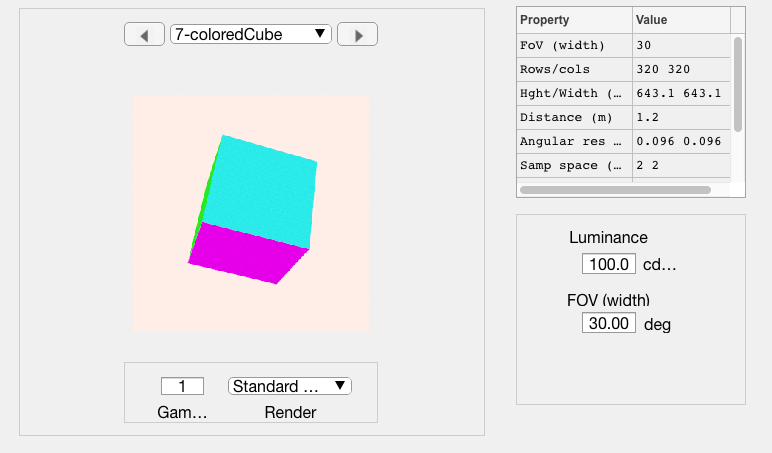

thisR.set('node', thisNode.name, 'rotate', [0 0 45]);
thisR.set('node', thisNode.name, 'scale', [1.3 1.3 1.3]);
piWRS(thisR,'name','coloredCube','render type','radiance');

## Translate and scale differs from scale and translate

thisR = piRecipeDefault('scene name','coloredCube');

Read 1 materials.
Read 1 textures.
***Scene parsed.


Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  38.7 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


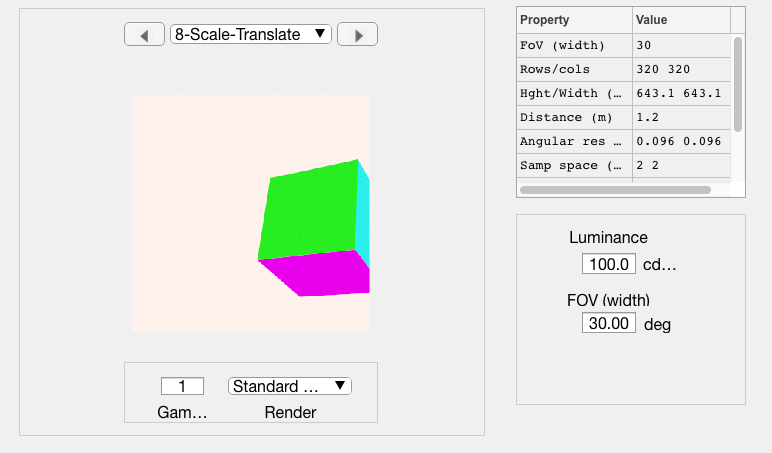

thisR.set('node', thisNode.name, 'scale', [1.3 1.3 1.3]);
thisR.set('node', thisNode.name, 'translate', [0.3 0.3 0]);
piWRS(thisR,'name','Scale-Translate','render type','radiance');

thisR = piRecipeDefault('scene name','coloredCube');

Read 1 materials.
Read 1 textures.
***Scene parsed.


Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube":"/Users/wandell/Documents/MATLAB/iset3d/local/coloredCube" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/renderings/coloredCube.dat /Users/wandell/Documents/MATLAB/iset3d/local/coloredCube/coloredCube.pbrt
*** Rendering time for coloredCube:  30.8 sec ***

  Reading image h=320 x w=320 x 31 spectral planes.


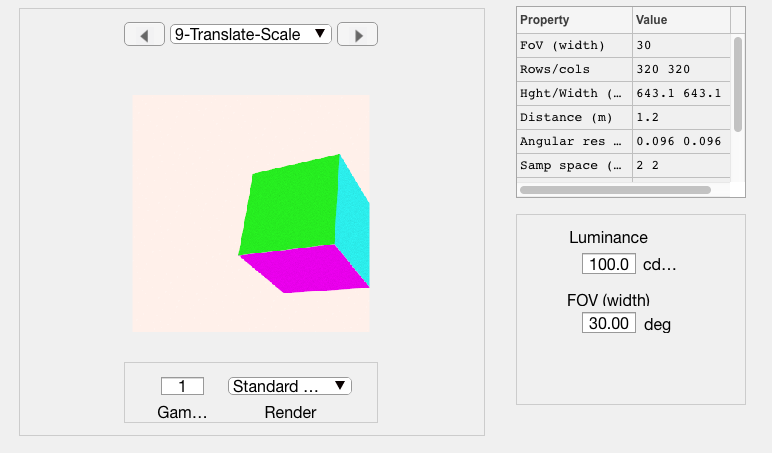


thisR.set('node', thisNode.name, 'translate', [0.3 0.3 0]);
thisR.set('node', thisNode.name, 'scale', [1.3 1.3 1.3]);
scene = piWRS(thisR,'name','Translate-Scale');